## Read Task File

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mohammad\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


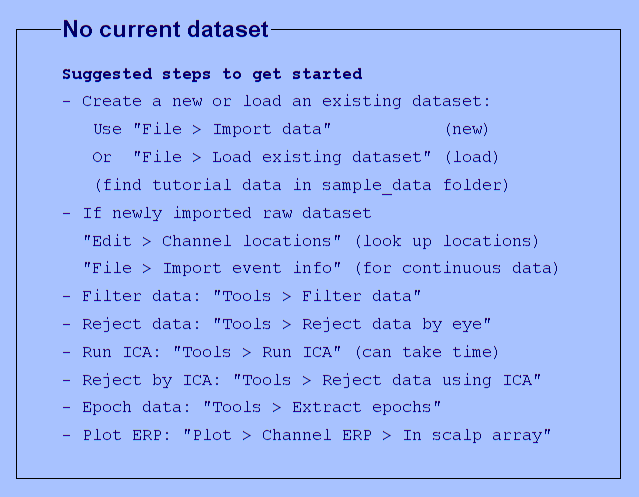

You are using the latest version of EEGLAB.


clear all
eeglab

T = readtable('task_track_file.csv','Format','%d%s%s%s%s%s%s')

T = 75×7 table
    Var1        local_file_path                 raw_data_file_name                         preprocessed_one                              ERP_mat_file                                    PAC_dist                                   PAC_dist_mean_channel            
    ____    _______________________    ____________________________________    ________________________________________    ________________________________________    _____________________________________________    _____________________________________________

      0     {'sub-001\ses-01\eeg\'}    {'sub-001_ses-01_task-Rest_eeg.set'}    {'pre_sub-001_ses-01_task-Rest_eeg.set'}    {'ERP_sub-001_ses-01_task-Rest_eeg.mat'}    {'PAC_dist_sub-001_ses-01_task-Rest_eeg.mat'}    {'PAC_

Path = {'/home/kiani/DS/ds003490-download'};
files_preprocessed = fullfile(Path,T{:,2},T{:,4});
flag = isfile(files_preprocessed);
task_not_completed = find(flag==0)';
temp = size(task_not_completed);

a = T{:,4}

a = 75×1 cell array
    {'pre_sub-001_ses-01_task-Rest_eeg.set'}
    {'pre_sub-001_ses-02_task-Rest_eeg.set'}
    {'pre_sub-002_ses-01_task-Rest_eeg.set'}
    {'pre_sub-002_ses-02_task-Rest_eeg.set'}
    {'pre_sub-003_ses-01_task-Rest_eeg.set'}
    {'pre_sub-004_ses-01_task-Rest_eeg.set'}
    {'pre_sub-004_ses-02_task-Rest_eeg.set'}
    {'pre_sub-005_ses-01_task-Rest_eeg.set'}
    {'pre_sub-006_ses-01_task-Rest_eeg.set'}
    {'pre_sub-006_ses-02_task-Rest_eeg.set'}
    {'pre_sub-007_ses-01_task-Rest_eeg.set'}
    {'pre_sub-007_ses-02_task-Rest_eeg.set'}
    {'pre_sub-008_ses-01_task-Rest_eeg.set'}
    {'pre_sub-008_ses-02_task-Rest_eeg.set'}
    {'pre_sub-009_ses-01_task-Rest_eeg.set'}
    {'pre_sub-009_ses-02_task-Rest_eeg.set'}
    {'pre_sub-010_ses-01_task-Rest_eeg.set'}
    {'pre_sub-010_ses-02_task-Rest_eeg.set'}
    {'pre_sub-011_ses-01_task-Rest_eeg.set'}
    {'pre_sub-011_ses-02_task-Rest_eeg.set'}
    {'pre_sub-012_ses-01_task-Rest_eeg.set'}
    {'pre_sub-012_ses-02_task-Rest_

a{5}

ans = 'pre_sub-003_ses-01_task-Rest_eeg.set'

## Preprocess

Highpass_low = 1; % in Hz
Highpass_High = 150; % in Hz
Notch_low = 59.9; % in Hz
Notch_High = 60.1;% in Hz
Notch_order = 16500;

Path = 'G:\\filmuniversity\\Master sharif\\MasterProject\\data\\parkinsons-oddball';
channellocationfile = fullfile({Path},T{1,2}{1},'sub-001_ses-01_task-Rest_electrodes.tsv');
channellocationfile = channellocationfile{1}

channellocationfile = 'G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_electrodes.tsv'

delete(gcp('nocreate'))
parpool(2)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 2
              Cluster: 

a=T{:,2};
b=T{:,3};
c=T{:,4};
parfor i=task_not_completed
    load_path = sprintf('%s\\%s',Path,a{i});
    EEG = pop_loadset(b{i},load_path);
    EEG = pop_chanedit(EEG,'load',{channellocationfile ,'filetype','autodetect'});
    EEG = pop_select( EEG, 'nochannel',{'X','Y','Z','VEOG'});
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Notch_low,'hicutoff',Notch_High,'filtorder',Notch_order,'revfilt',1);
    EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',12,'Highpass','off','BurstCriterion','off','WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_interp(EEG1, EEG.chanlocs, 'spherical');
    EEG = pop_reref( EEG, []);
    EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',15,'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_reref( EEG, []);
    EEG = pop_saveset( EEG, 'filename',c{i},'filepath',load_path);
end

pop_loadset(): loading file G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-002\ses-02\eeg\sub-002_ses-02_task-Rest_eeg.set ...
pop_loadset(): loading file G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-004\ses-01\eeg\sub-004_ses-01_task-Rest_eeg.set ...
Reading float file 'G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-002\ses-02\eeg\sub-002_ses-02_task-Rest_eeg.fdt'...
readlocs(): 'tsv' format assumed from file extension
Reading float file 'G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-004\ses-01\eeg\sub-004_ses-01_task-Rest_eeg.fdt'...
readlocs(): 'tsv' format assumed from file extension
Removing 4 channel(s)...
Event resorted by increasing latencies.
Removing 4 channel(s)...
Event resorted by increasing latencies.
pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transiti